# Wavefront Path Planning

**Date:** May 2, 2026

**Purpose:** This script demonstrates the **Wavefront (Distance Transform)** algorithm for robotic path planning. It provides a visual, step-by-step simulation of how a robot can navigate a grid-based map from a start point to a goal while avoiding obstacles.

#### Pseudo Code

## Step 1: Map Initialization

Defining the environment and setting the obstacle locations.

clear;
% 1. Initialize the MAP (0 = Free Space, 1 = Obstacle)
MAP = zeros(6,11);

% 2. Define obstacles [row col]
obs = [1 4; 1 5; 1 6; 1 7; 2 9; 2 11; 3 3; 3 7; 3 9; ...
    4 3; 4 4; 4 6; 4 7; 4 9; 5 6; 5 7; 5 10; 6 6; 6 7];

% Convert obstacle coordinates to linear indices and apply to MAP
linearIdx = sub2ind(size(MAP), obs(:,1), obs(:,2));
MAP(linearIdx) = 1;

% 3. Set Start and Goal nodes
start = [1 8];
goal = [6 2];

% --- SAFETY CHECK ---
% Verify that Start and Goal are not on obstacles
if MAP(start(1), start(2)) == 1 || MAP(goal(1), goal(2)) == 1
    error('Invalid Input: Start or Goal is placed on an obstacle!');
end

% 4. Setup Figure and Visuals
f1 = figure('Name','Wavefront Animation', 'Visible','on');
set(f1, 'Position', [200, 200, 400, 400]);
h = imagesc(MAP); 
title({'Wavefront'}, {'Phase 1 (Propagation)'});
axis square; colormap([0.5 0.5 0.5; 0 0 0; 0 0 1]); clim([0 2]);
[rows, cols] = size(MAP);

% Create text handles for real-time cost updates
txt_handles = gobjects(rows, cols); 
for r = 1:rows
    for c = 1:cols
        txt_handles(r,c) = text(c, r, num2str(MAP(r,c)), ...
            'HorizontalAlignment', 'center', 'Color', 'white');
    end
end

## Step 2: Phase 1 - Wavefront Propagation

The algorithm explores the map using a Breadth-First Search (BFS) starting from the **Goal**.

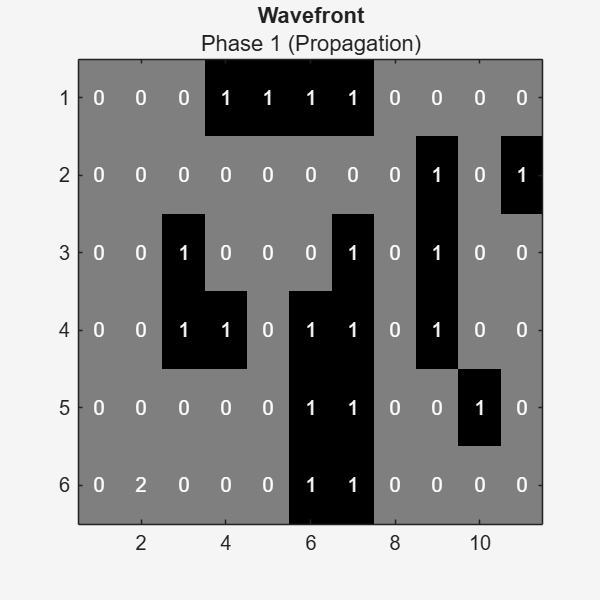

% Initialization for Propagation
map = MAP; 
currentValue = 2; % The Goal is always initialized to 2
map(goal(1), goal(2)) = currentValue;
txt_handles(goal(1), goal(2)).String = num2str(currentValue);


queue = goal; % BFS Queue starts at the goal
foundStart = false;
connectedness = 4; % Choose 4 or 8

% Pre-define neighbor offsets for speed
if connectedness == 4
    offsets = [-1 0; 1 0; 0 -1; 0 1]; 
else
    offsets = [-1 0; 1 0; 0 -1; 0 1; -1 -1; -1 1; 1 -1; 1 1];
end

% ---------- WAVE PROPAGATION LOOP ----------
% Continue propagation as long as there are cells to explore (Queue not empty) 
% and the Start has not yet been reached (foundStart is false).
while ~isempty(queue) && ~foundStart
    currentCell = queue(1,:)
    currentValue = map(currentCell(1), currentCell(2));
    queue(1,:) = []; % Dequeue

    allNeighbors = currentCell + offsets

    for j = 1:size(allNeighbors, 1)
        nr = allNeighbors(j, 1);
        nc = allNeighbors(j, 2);

        % Boundary and Obstacle/Visited Check
        if nr>=1 && nr<= rows && nc>=1 && nc<=cols
            if map(nr, nc) == 0 % If cell is un-visited free space
                map(nr, nc) = currentValue + 1;
                txt_handles(nr, nc).String = num2str(map(nr, nc));

                queue = [queue; nr, nc]; % Enqueue

                if nr == start(1) && nc == start(2)
                    foundStart = true;
                    break;
                end
            end
        end
    end
    set(h, 'CData', map); % Update visual map
    drawnow;
end

currentCell =      6     2


allNeighbors =      5     2
     7     2
     6     1
     6     3


## Step 3: Phase 2 - Backtracking

Once the "wave" reaches the Start, decreasing gradient of costs to find the shortest path back to the Goal.

if foundStart
    title({'Wavefront'}, {'Phase 2 (Backtracking)'});
    currentCell = start;
    path = currentCell;
    
    % ---------- BACKTRACKING LOOP ----------
    % Continue until we reach the Goal (Value = 2)
    while map(currentCell(1), currentCell(2)) > 2
        allNeighbors = currentCell + offsets;

        for j = 1:size(allNeighbors, 1)
            nr = allNeighbors(j, 1);
            nc = allNeighbors(j, 2);

            if nr>=1 && nr<= rows && nc>=1 && nc<=cols
                % Move to the neighbor with exactly Cost - 1
                if map(nr, nc) == map(currentCell(1), currentCell(2)) - 1
                    currentCell = [nr nc];
                    path = [path; currentCell];
                    break;
                end
            end
        end
    end
    
    % Calculate Path Length (number of edges/steps)
    pathLength = size(path, 1) - 1; 

    % ---------- Final Visualization ----------
    hold on;
    plot(path(:,2), path(:,1), 'r-', 'LineWidth', 3); % Plot path line
    plot(path(1,2), path(1,1), 'go', 'MarkerSize', 12, 'MarkerFaceColor','g'); % Start
    plot(path(end,2), path(end,1), 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Goal
    uistack(txt_handles(:), 'top'); % Keep numbers visible over the line
    title({'Wavefront Complete'}, {['Path Found : ', num2str(pathLength), ' steps']});
else
    title({'Wavefront Complete'}, {'No Path Possible'});
end